`Pràctica`

`Es demana:`

`(a)`` Aproximeu aquests punts per polinomis de grau 11 fins a 1010 sota el criteri de mínims quadrats. Estudieu l’error que es produeix avaluant els polinomis de punts intermedis i comparant el resultat amb el seu valor exacte. `

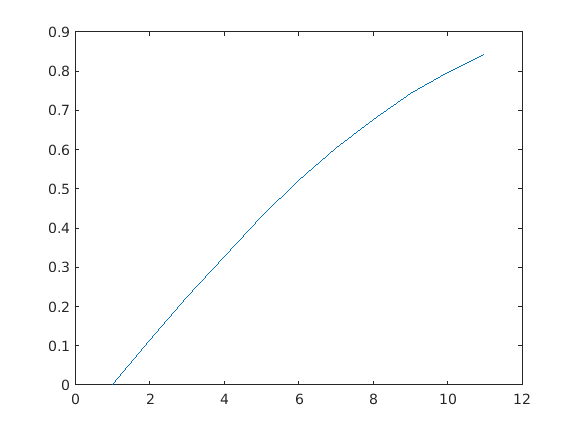

%inicialitzacions
t=@(i)(i-1)/10;
n = (1:11)';
t2 = [t(n)];
y=erf(t2);
plot(y)

intermedis = zeros(11);
error = zeros(11);
for x=1:11;
    x;
    coefficients = polyfit(n,y,x);
    plot(coefficients);
    curve = polyval(coefficients,n);
    for i=1:11;
        intermedis(i,x) = curve(i);
        errorA(i,x) = abs(y(i)-curve(i));
    end
    plot(curve)
end

format long
errorA;
xdca = zeros(11);
for i=1:11;
    for j=1:11;
        decimal = 0;
        while errorA(i,j) < 0.5*10^-decimal;
            decimal = decimal + 1;
        end
        xdca(i,j) = decimal;
    end
end


`(b)`` Com que 𝑒𝑟𝑓(𝑡) és una funció senar, sembla raonable d’aproximar les mateixes dades per una combinació lineal de potències senars de 𝑡`

A = [t2 t2.^3 t2.^5 t2.^7 t2.^9];
b = [erf(t2)];
x=linsolve(A,b);
sol = A*x; 
Rb=[y sol];
plot(sol)

format long
errorb=abs(y-sol);
xdcb = zeros(11,1);
for i=1:11;
    decimal = 0;
    while errorb(i) < 0.5*10^-decimal;
        decimal = decimal + 1;
    end
    xdcb(i) = decimal;  
end


`(c)`` Els polinomis no són una bona base per aproximar a la funció d’error, ja que no estant fitats per a valors grans de 𝑡 i, en canvi, 𝑒𝑟𝑓(𝑡) tendeix a 1 per a valors grans de 𝑡. Utilitzant el mateix conjunt de punts aproximeu de la forma seguent:`

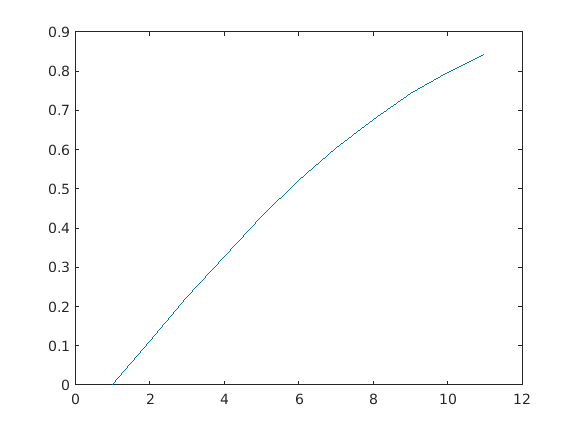

for i=1:11
    if i == 1
        R1 = [exp(-t2(i).^2)'*(1/1+t2(i)) ];
        R2 = [exp(-t2(i).^2)'*(1/1+t2(i)).^2 ];
        R3 = [exp(-t2(i).^2)'*(1/1+t2(i)).^3 ];
    else 
        R1 = [R1;exp(-t2(i).^2)'*(1/1+t2(i)) ];
        R2 = [R2;exp(-t2(i).^2)'*(1/1+t2(i)).^2 ];
        R3 = [R3;exp(-t2(i).^2)'*(1/1+t2(i)).^3 ];
    end
end
C1 = [1 1 1 1 1 1 1 1 1 1 1]';
R0 = exp(-t2.^2);
A = [C1 R0 R1 R2 R3];
b = [erf(t2)];
x=linsolve(A,b);
sol = A*x;
Rc=[y sol];
plot(sol)

format long
errorc =abs(y-sol);
xdcc = zeros(11,1);
for i=1:11;
    decimal = 0;
    while errorc(i) < 0.5*10^-decimal;
        decimal = decimal + 1;
    end
    xdcc(i) = decimal;  
end

`d) ``Presenteu els resultats de cada apartat en una taula. ` `Comenteu i argumenteu els resultats obtinguts.`

**Resultats de l'apartat a**

%valors intermedis dels polinomis 1..11
Ta=array2table(intermedis)

Ta = 11×11 table
       intermedis1           intermedis2             intermedis3            intermedis4             intermedis5             intermedis6              intermedis7              intermedis8             intermedis9             intermedis10             intermedis11    
    _________________    ____________________    ___________________    ____________________    ____________________    ____________________    _____________________    _____________________    ____________________    _____________________    ____________________

    0.053127755600462    -0.00634545069301326    -0.0011712091350265    1.875787

%error absoluts
array2table(errorA)

ans = 11×11 table
          errorA1                errorA2                 errorA3                 errorA4                 errorA5                 errorA6                 errorA7                 errorA8                 errorA9                 errorA10                errorA11      
    ___________________    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________    ____________________

      0.053127755600462     0.00634545069301326      0.0011712091350265    1.87

%número de xifres decimal correctes
array2table(xdca)

ans = 11×11 table
    xdca1    xdca2    xdca3    xdca4    xdca5    xdca6    xdca7    xdca8    xdca9    xdca10    xdca11
    _____    _____    _____    _____    _____    _____    _____    _____    _____    ______    ______

      1        2        3        5        5        7        8       10       12        17        13  
      2        3        3        5        5        7        7        9       11       324        13  
      3        3        3        5        5        7        7        9       10        16        13  
      2        3        4        5        5        7        7        8       10        16        

Segons els resultats obtinguts, amb aquest mètode, s'aconsegueixen millors resultats amb graus de polinomis grans.

**Resultats de l'apartat b**

Tb=array2table(Rb,'VariableNames',{'y','curve'})

Tb = 11×2 table
            y                  curve      
    _________________    _________________

                    0                    0
    0.112462916018285    0.112462555665377
    0.222702589210478    0.222702307079481
    0.328626759459127    0.328626918201992
    0.428392355046668    0.428392762830696
    0.520499877813047    0.520499955811062
    0.603856090847926    0.603855675494494
    0.677801193837418    0.677801007361632
    0.742100964707661    0.742101509727097
    0.796908212422832    0.796907916192274
    0.842700792949715    0.842700846012791


array2table(errorb)

ans = 11×1 table
           errorb       
    ____________________

                       0
    3.60352907624595e-07
    2.82130997564245e-07
    1.58742864131423e-07
    4.07784028044755e-07
    7.79980152687543e-08
    4.15353431537646e-07
    1.86475786811968e-07
    5.45019436470895e-07
    2.96230558638477e-07
    5.30630762662909e-08


array2table(xdcb)

ans = 11×1 table
    xdcb
    ____

    324 
      7 
      7 
      7 
      7 
      7 
      7 
      7 
      6 
      7 
      7 


Segons els resultats obtinguts, amb aquest mètode, s'aconsegueixen bons resultats però tenen un menor nombre de xifres decimals correctes que en l'apartat anterior amb polinomis de graus alts.

**Resultats de l'apartat c**

Tc=array2table(Rc,'VariableNames',{'y','curve'})

Tc = 11×2 table
            y                   curve        
    _________________    ____________________

                    0    0.000147181511306493
    0.112462916018285       0.112160161722631
    0.222702589210478       0.222688327957718
    0.328626759459127       0.328837675470776
    0.428392355046668       0.428546466173133
    0.520499877813047       0.520441232465348
    0.603856090847926       0.603657179268138
    0.677801193837418       0.677674674073777
    0.742100964707661       0.742205688556301
    0.796908212422832       0.797141425069703
    0.842700792949715       0.842551740044324


array2table(errorc)

ans = 11×1 table
           errorc       
    ____________________

    0.000147181511306493
    0.000302754295654351
    1.42612527600505e-05
    0.000210916011648188
    0.000154111126464296
     5.8645347698949e-05
     0.00019891157978813
    0.000126519763641753
    0.000104723848640131
    0.000233212646870928
    0.000149052905390801


array2table(xdcc)

ans = 11×1 table
    xdcc
    ____

     4  
     4  
     5  
     4  
     4  
     4  
     4  
     4  
     4  
     4  
     4  


Segons els resultats obtinguts, amb aquest mètode, s'aconsegueixen resultats relativament pitjors que en els apratats anteriors.